# Run Your Function

Calling with four inputs

This works correctly.

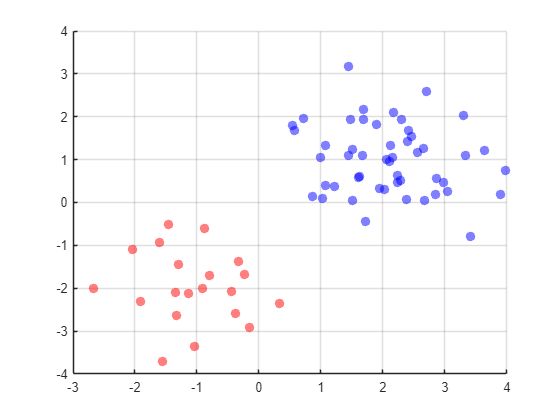

xall = 1×2 cell array
    {20×1 double}    {50×1 double}


yall = 1×2 cell array
    {20×1 double}    {50×1 double}


colors = 1×2 cell array
    {["r"]}    {["b"]}


rng(123)
x1 = -1 + randn(20, 1);
y1 = -2 + randn(20, 1);
x2 = 2 + randn(50, 1);
y2 = 1 + randn(50, 1);
[xall, yall, colors] = multiscatter(x1, y1, "r", x2, y2, "b")

**Calling with varying inputs**

These calls to `multiscatter` currently error, but you will fix in this activity.

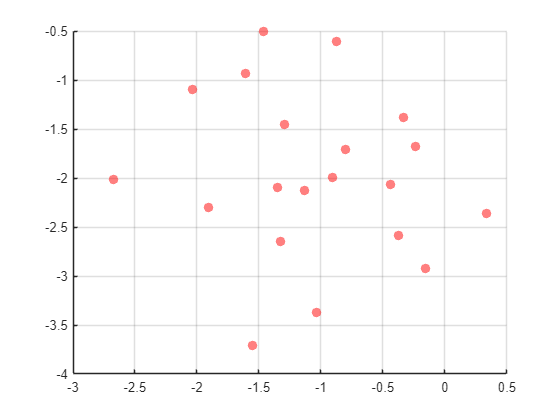

xall = 1×1 cell array
    {20×1 double}


yall = 1×1 cell array
    {20×1 double}


colors = 1×1 cell array
    {["r"]}


[xall, yall, colors] = multiscatter(x1, y1, "r")

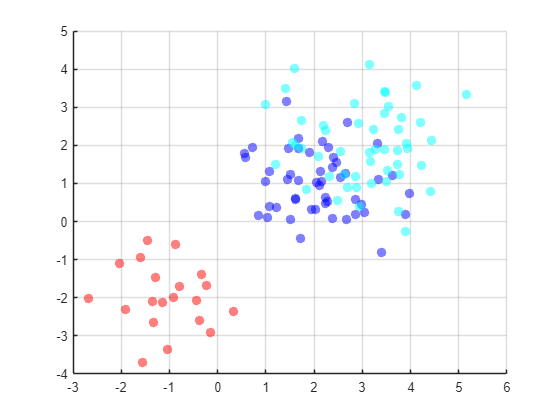

xall = 1×3 cell array
    {20×1 double}    {50×1 double}    {50×1 double}


yall = 1×3 cell array
    {20×1 double}    {50×1 double}    {50×1 double}


colors = 1×3 cell array
    {["r"]}    {["b"]}    {["c"]}


x3 = 3 + randn(50, 1);
y3 = 2 + randn(50, 1);
[xall, yall, colors] = multiscatter(x1, y1, "r", x2, y2, "b", x3, y3, "c")

# Create scatter plot for vectors in specified colors

`x1,y1,c1,x2,y2,c2,x3,y3,c3...` are the inputs to plot along with the corresponding color.

`x` is a cell array of the vectors that make up the x-data.

`y` is a cell array of the vectors that make up the y-data.

`c` is a cell array of the colors to plot the respective data.

The function `multiscatter` makes a scatter plot from two different sets of (x,y) data, each in a different color specified by the user.

function [x,y,c] = multiscatter(varargin)
    % Collect cell arrays of x, y, and c
    x = varargin(1:3:end);
    y = varargin(2:3:end);
    c = varargin(3:3:end);
    
    % Make plots
    figure
    grid on
    hold on
    for k = 1:numel(x)
        scatter(x{k},y{k},50,c{k},"filled","MarkerFaceAlpha",0.5)
    end
    hold off
end